x = load('1.txt')

x =      0     0     0     0     0   404
     1     0     0     0     0   392
     2     0     0     0     0   372
     3     0     0     0     0   353
     4     0     0     0     0   342
     5     0     0     0     0   348
     6     0     0     0     0   347
     7     0     0     0     0   339
     8     0     0     0     0   334
     9     0     0     0     0   333



S=x(:,6);

sp=105101

sp = 105101

ep=107100

ep = 107100


S=S(sp:ep) %RAW

S =    961
   927
   889
   865
   870
   880
   888
   891
   885
   871



s = S

s =    961
   927
   889
   865
   870
   880
   888
   891
   885
   871


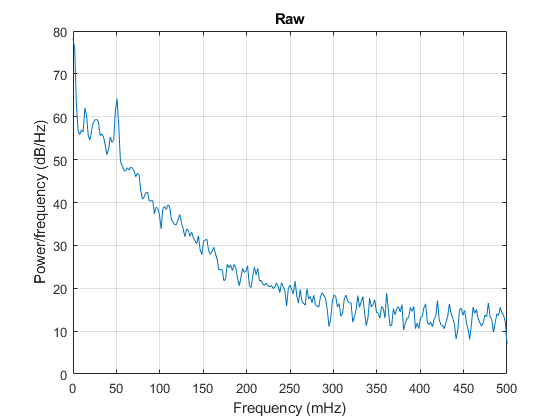


waveletFunction = 'db8';
[C,L] = wavedec(S,8,waveletFunction);

cD1 = detcoef(C,L,1); %NOISY
cD2 = detcoef(C,L,2); %NOISY
cD3 = detcoef(C,L,3); %NOISY
cD4 = detcoef(C,L,4); %NOISY
cD5 = detcoef(C,L,5); %GAMA
cD6 = detcoef(C,L,6); %BETA
cD7 = detcoef(C,L,7); %ALPHA
cD8 = detcoef(C,L,8); %THETA
cA8 = appcoef(C,L,waveletFunction,8); %DELTA


%%%% Calculation the Details Vectors
d1 = wrcoef('d',C,L,waveletFunction,1); %NOISY
d2 = wrcoef('d',C,L,waveletFunction,2); %NOISY
d3 = wrcoef('d',C,L,waveletFunction,3); %NOISY
d4 = wrcoef('d',C,L,waveletFunction,4); %NOISY
d5 = wrcoef('d',C,L,waveletFunction,5); %GAMMA
d6 = wrcoef('d',C,L,waveletFunction,6); %BETA
d7 = wrcoef('d',C,L,waveletFunction,7); %ALPHA
d8 = wrcoef('d',C,L,waveletFunction,8); %THETA
a8 = wrcoef('a',C,L,waveletFunction,8); %DELTA


figure; pwelch(s, [], [], [], 1), title("Raw")



[pxx1,f1] = pwelch( s, 10, [], [], 1000)

pxx1 = 	1.0e+03 *

    1.8323
    3.6570
    3.6344
    3.5969
    3.5451
    3.4795
    3.4009
    3.3101
    3.2083
    3.0965


f1 =          0
    3.9063
    7.8125
   11.7188
   15.6250
   19.5313
   23.4375
   27.3438
   31.2500
   35.1563


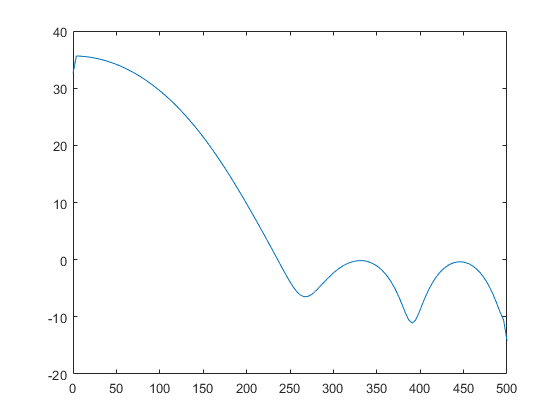

plot(f1,pow2db(pxx1))


[pxx2,f2] = pwelch( s, 100, [], [], 1000)

pxx2 = 	1.0e+04 *

    1.6833
    2.6558
    1.2806
    0.3729
    0.1016
    0.0723
    0.0696
    0.0635
    0.0520
    0.0394


f2 =          0
    3.9063
    7.8125
   11.7188
   15.6250
   19.5313
   23.4375
   27.3438
   31.2500
   35.1563


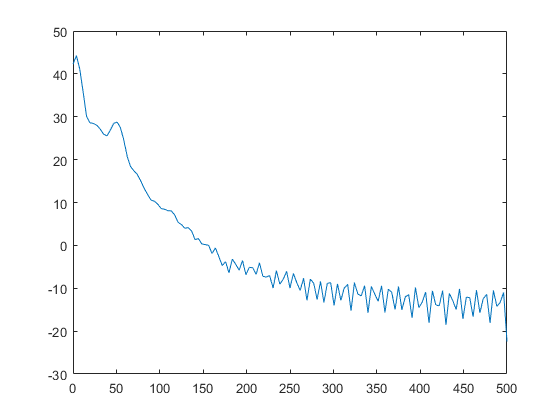

plot(f2,pow2db(pxx2))


[pxx3,f3] = pwelch(  s, 1000, [], [], 1000)

pxx3 = 	1.0e+05 *

    1.4476
    0.6230
    0.0509
    0.0117
    0.0088
    0.0051
    0.0056
    0.0035
    0.0031
    0.0060


f3 =          0
    0.9766
    1.9531
    2.9297
    3.9063
    4.8828
    5.8594
    6.8359
    7.8125
    8.7891


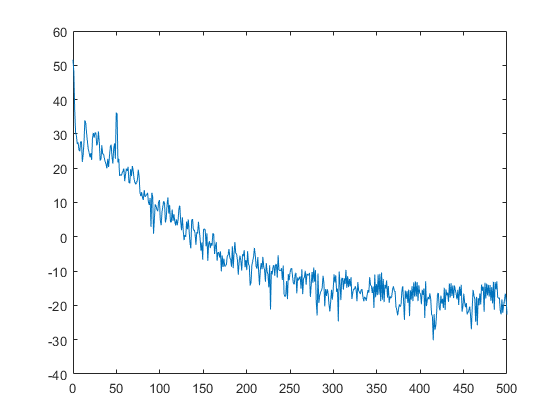

plot(f3,pow2db(pxx3))

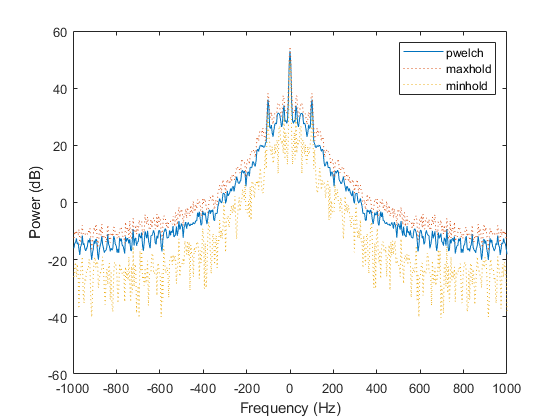


x = s;
Fs = 2000;

[pxx,f] = pwelch(  x,[],[],[],Fs,'centered','power');
pmax = pwelch(x,[],[],[],Fs,'maxhold','centered','power');
pmin = pwelch(x,[],[],[],Fs,'minhold','centered','power');

plot(f,pow2db(pxx))
hold on
plot(f,pow2db([pmax pmin]),':')
hold off
xlabel('Frequency (Hz)')
ylabel('Power (dB)')
legend('pwelch','maxhold','minhold')

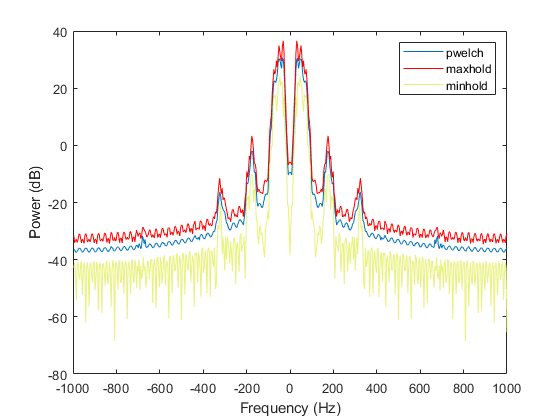


x = d5;
Fs = 2000;

[pxx,f] = pwelch(x,[],[],[],Fs,'centered','power');
pmax = pwelch(x,[],[],[],Fs,'maxhold','centered','power');
pmin = pwelch(x,[],[],[],Fs,'minhold','centered','power');

plot(f,pow2db(pxx))
hold on
plot(f,pow2db([pmax]), 'Color',[1, 0, 0])
hold on
plot(f,pow2db([pmin]),'Color', [0.905, 0.952, 0.486])
hold off
xlabel('Frequency (Hz)')
ylabel('Power (dB)')
legend('pwelch','maxhold','minhold')